# Preprocess Permanent Magnet Synchronous Motor (PMSM) Data and Autogenerate Current Controller Calibration Tables

이 스크립트를 사용하여 모델 기반 캘리브레이션(MBC)에 사용할 PMSM 데이터를 사전 처리하고 calibratepmsm 함수를 사용하여 현재 컨트롤러 캘리브레이션 테이블을 자동 생성할 수 있습니다. 이 스크립트는 MBC에서 사용할 테이블 개체인 MBCdata를 생성합니다. 작업 공간에서 MBCdata 개체를 MBC로 가져오거나 이 개체를 calibratepmsm 함수와 함께 사용하여 PMSM에 대한 토크 테이블을 생성할 수 있습니다. 

PMSM 특성화 데이터는 유한 요소 분석 시뮬레이션 또는 동력계 테스트에서 얻을 수 있습니다. 

#### KDH comment

-> FEM simscape Model -> PMSM characteristic data -> Flux-based Model -> Vehicle Model (Mapped)?

#### Virtual Vehicle

#### 1. Battery Electric Vehicle Model in Simscape >detailedPMSM > FEM

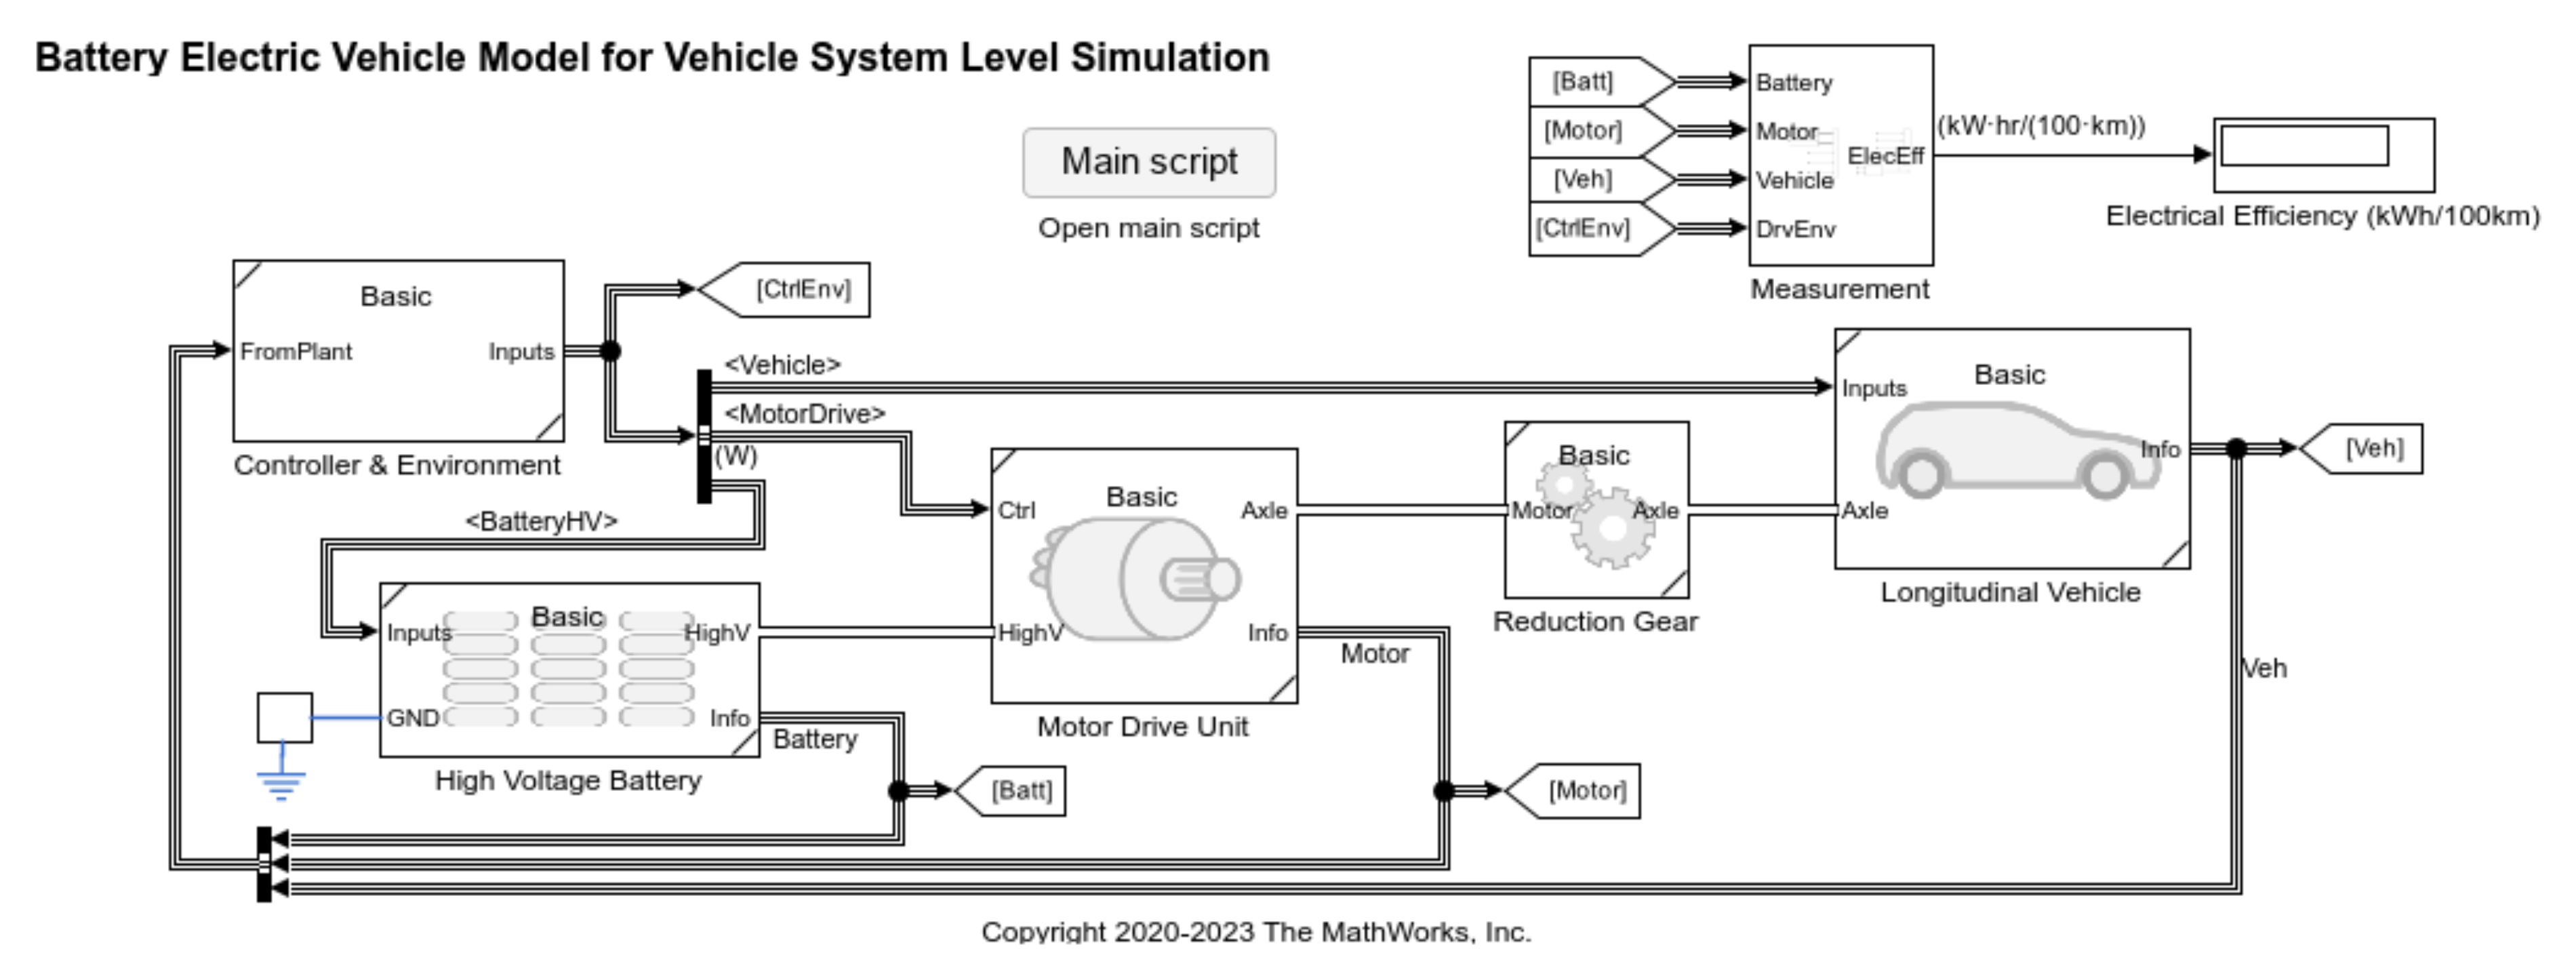

BEV 시스템 모델에서는 빠른 시뮬레이션을 위해 추상 모터 블록을 사용하지만, 이 블록에는 파라미터에 전기 손실 데이터가 필요합니다. 손실 데이터를 얻기 위해 보다 상세한 AC 3상 동기 모터와 FOC 컨트롤러가 사용됩니다.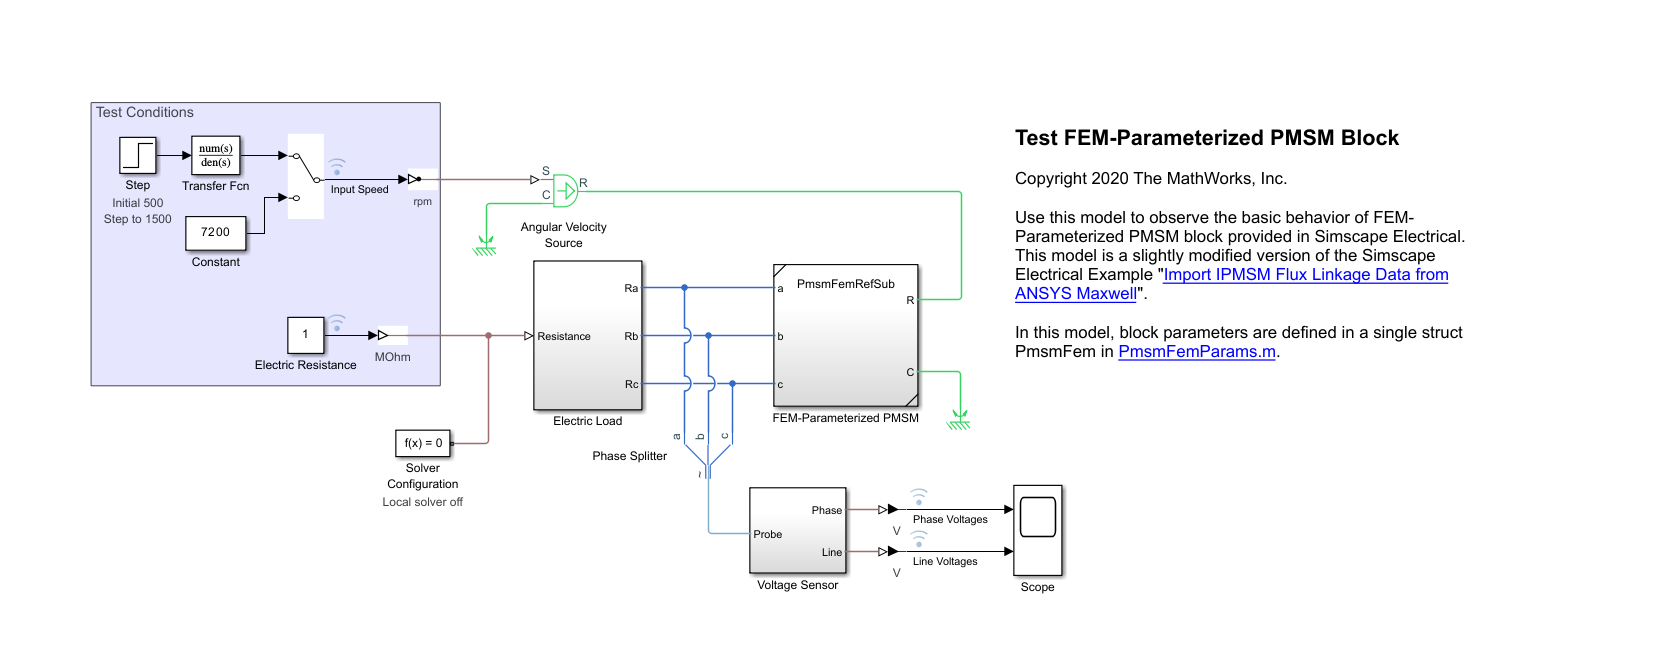

위에 사용된 PMSM 모델은 자기장 데이터를 기반으로 파라미터화된 것으로, 전자기 시스템 설계 툴에서 Simscape Electrical의 FEM 파라미터화된 PMSM 블록으로 가져온 것입니다.

- 저항부하로 FEM-PMSM 테스트

- 인버터로 FEM-PMSM 테스트

전류,전압 

Z:\01_Codes_Projects\git_MathworksBEV\DetailedModelApplications\MotorDrivePmsmFem\MotorDrive_runSim.mlx

효율맵까지

Z:\01_Codes_Projects\git_MathworksBEV\DetailedModelApplications\MotorDrivePmsmFem\MotorDrive_calcElectricEfficiency.mlx

 이 스크립트에서 생성된 손실 데이터는 빠른 시뮬레이션을 위해 **Simscape Electrical의 단순화된 PMSM 드라이브 블록에서 사용할 수 있습니다**.

#### 2. Detaild Electric Vehicle Design with Simscape™

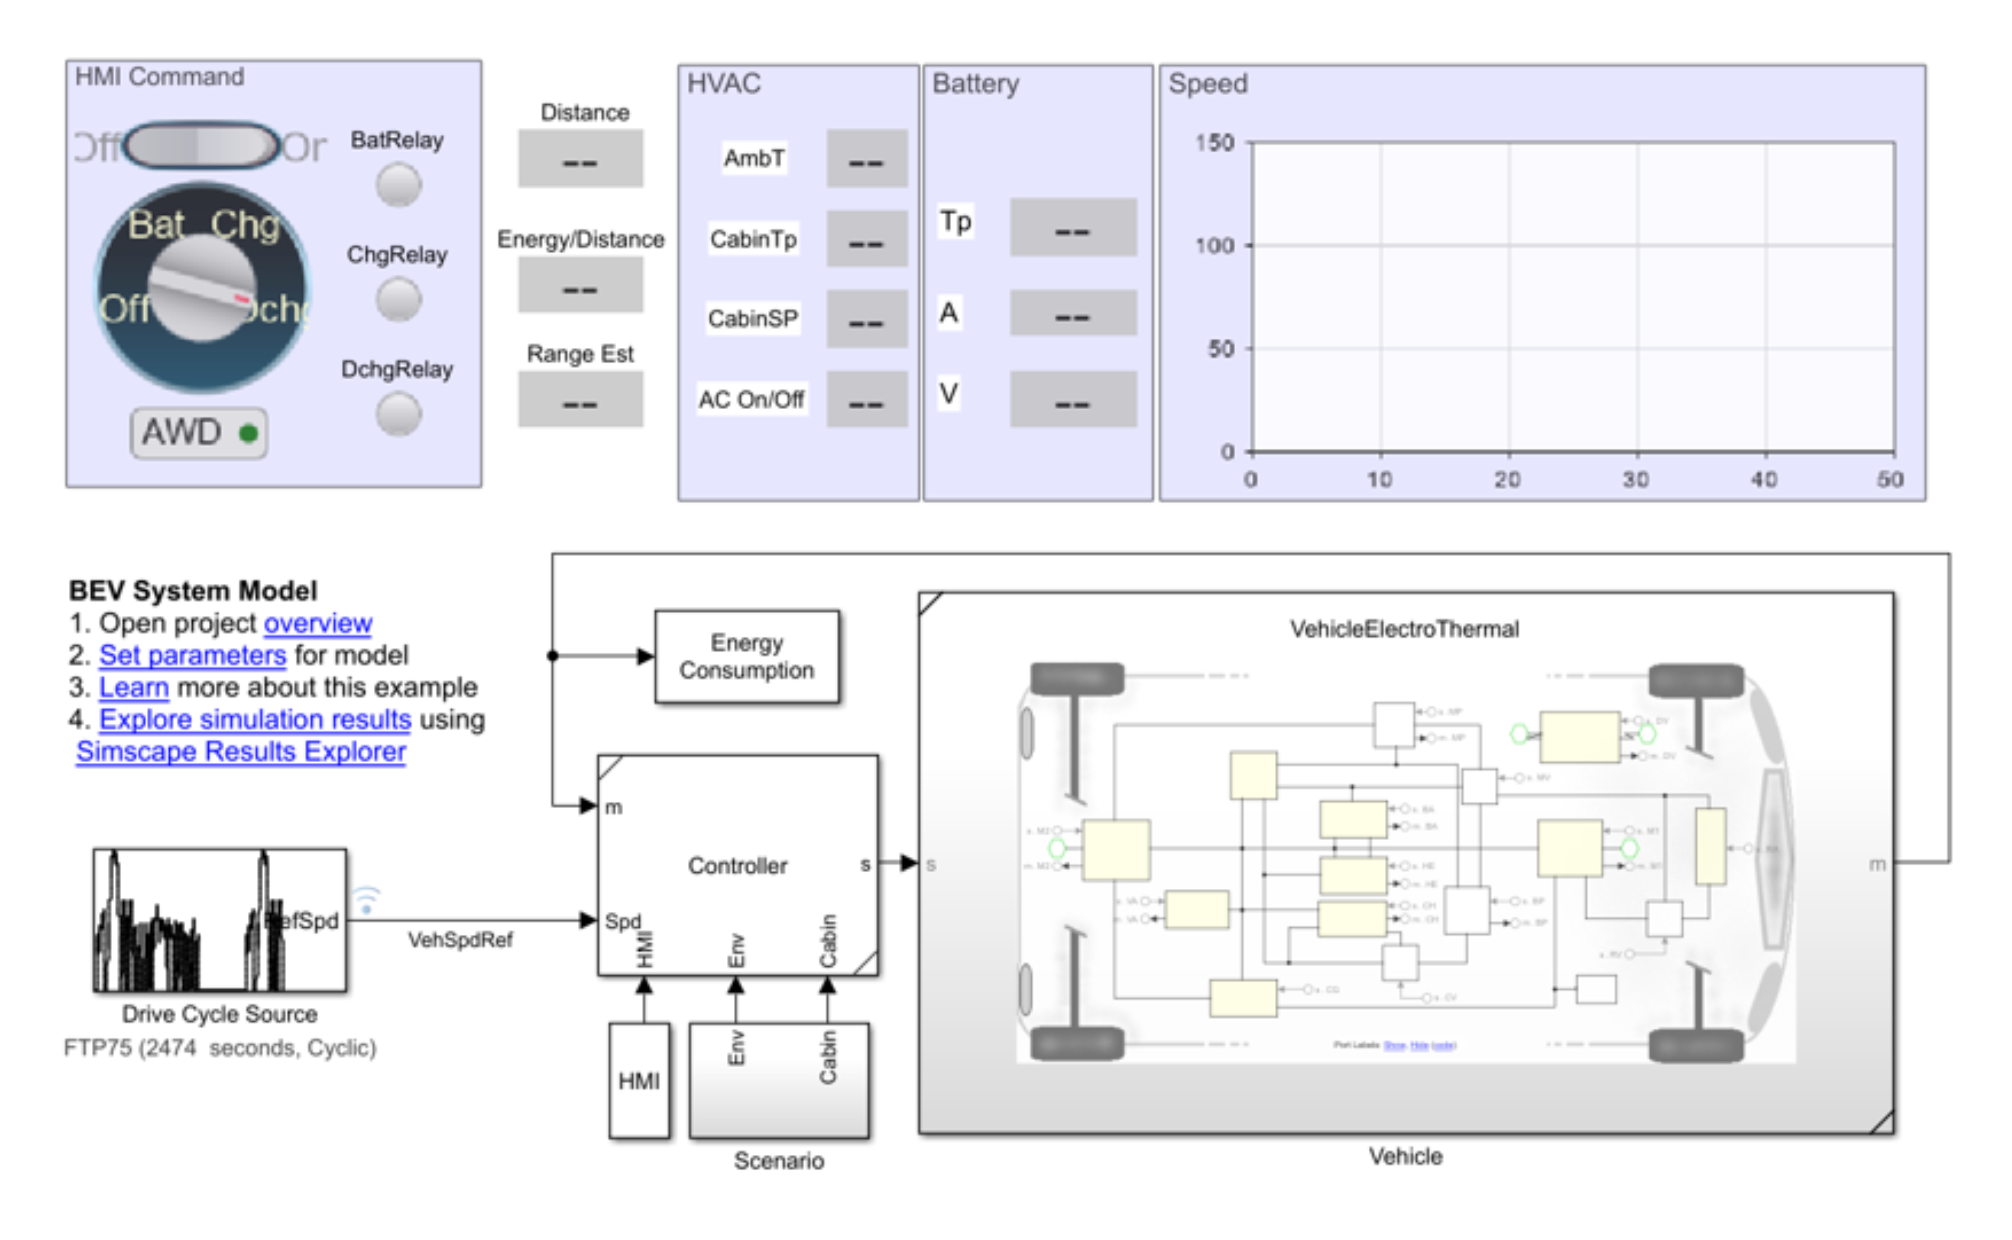

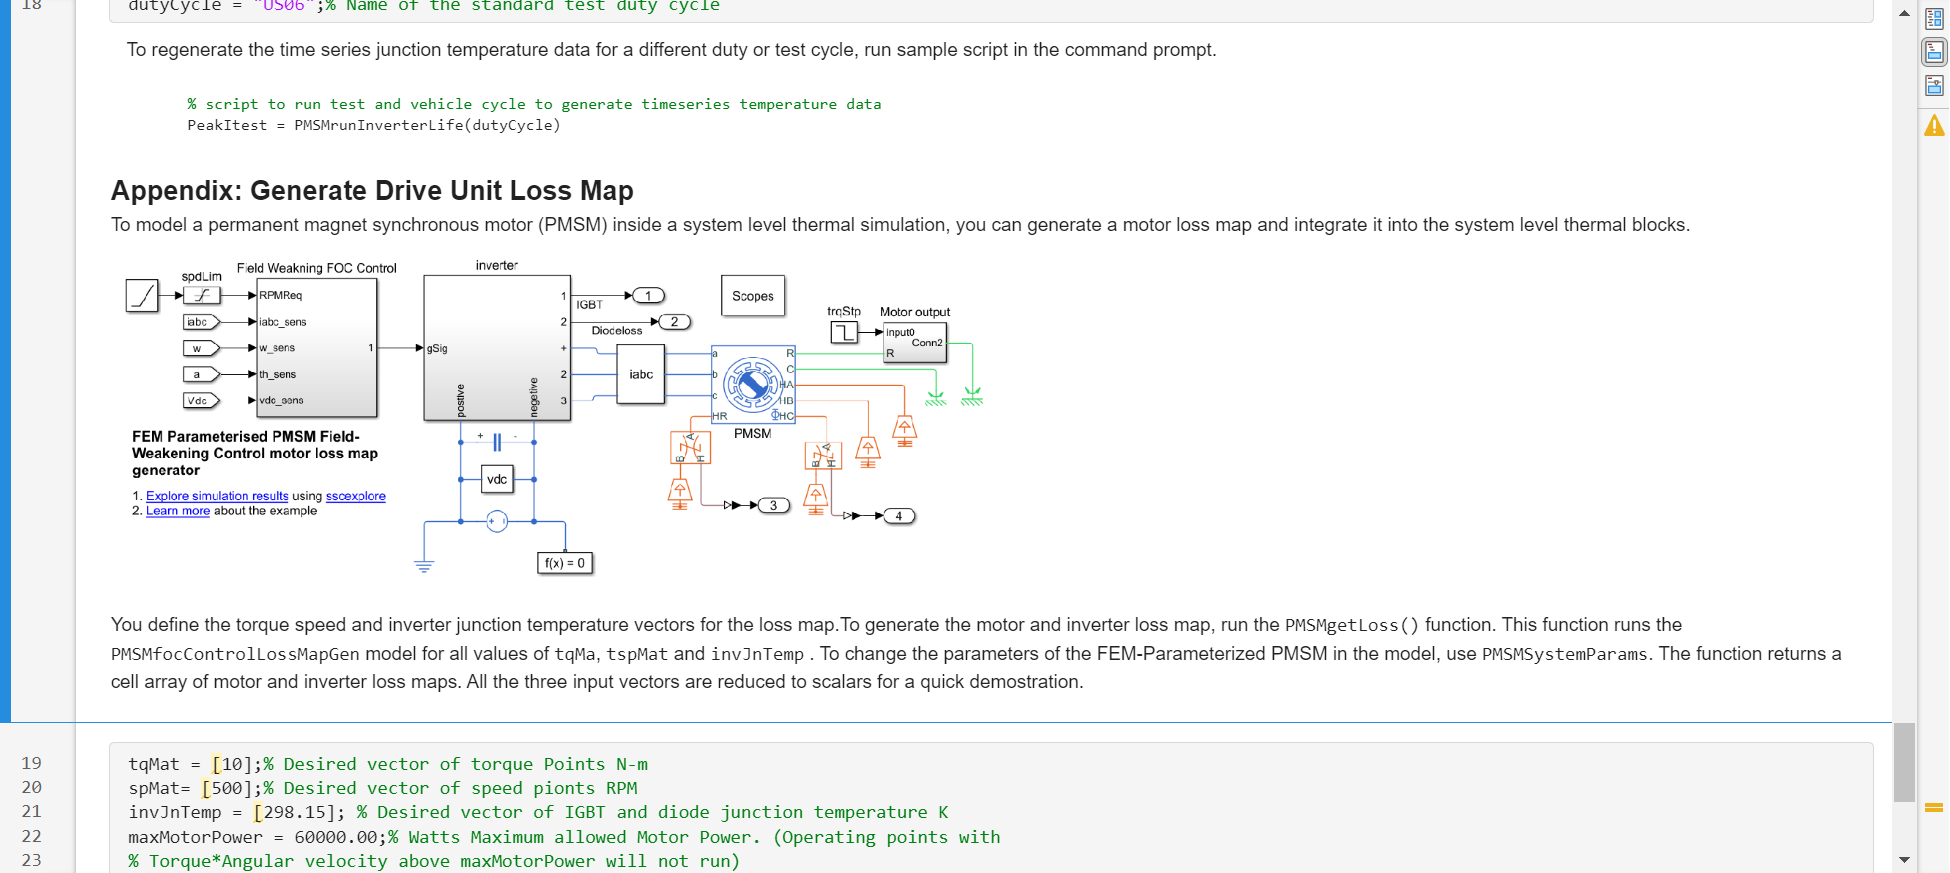

LossMap만들어서 

이건 온도포함해서 만드는듯

## **Generate Drive Unit Loss Map**

손실 맵에 대한 토크 속도 및 인버터 접합부 온도 벡터를 정의합니다. 모터 및 인버터 손실 맵을 생성하려면 PMSMgetLoss() 함수를 실행합니다. 이 함수는 tqMa, tspMat 및 invJnTemp의 모든 값에 대해 PMSMfocControlLossMapGen 모델을 실행합니다. 모델에서 FEM-파라미터화된 PMSM의 파라미터를 변경하려면 PMSMSystemParams를 사용합니다. 이 함수는 모터 및 인버터 손실 맵의 셀 배열을 반환합니다. 빠른 데모를 위해 세 개의 입력 벡터가 모두 스칼라로 축소됩니다.

PMSMgetLoss() 
PMSMfocControlLossMapGen
PMSMSystemParams

addpath(genpath(pwd))

% 굳이 밑에꺼 할필요가 없는거같은데

## Import Raw Data

Import the raw PMSM data from an Excel file.

fileName = "PMSM150kW.xlsx";

opts = detectImportOptions(fileName);

% read units if they are defined in the second row
if opts.DataRange=="A3"                 
    opts.VariableUnitsRange = "A2";
end

rawData = readtable(fileName, opts);

rawData =

## Use Standard Names for Required Channels

Save the variable names recognized by the MBC app to the array `standardNames`. Next, save the variable names from the imported spreadsheet to the array `actualNames`. Then, replace the imported variable names with the standard variable names. Channel names are read from the top row of the spreadsheet.

standardNames = ["Id", "Iq", "Fluxd", "Fluxq", "Trq"];
actualNames = ["I_d", "I_q", "Psi_d", "Psi_q", "Trq_msr"];
[ok,loc]=ismember(rawData.Properties.VariableNames,actualNames);
rawData.Properties.VariableNames(loc(ok)) = standardNames(ok);

## Define PMSM Specification

Specify the DC voltage `Vdc`, number of pole pairs `pp`, resistance `Rs`, phase peak current `IsMax`, and maximum modulation voltage `VsMax` to align with your PMSM specification. 

You may need to run tests at different levels of Vdc.

Vdc = 350;      % Voltage
pp = 4;
Rs = 0.0061;        % Ohm
IsMax = 615;     % Ampere
VsMax = Vdc*(2/pi);     % Voltage

## Define Operating Points

Specify the number of torque operating points `numTorqueLevels` and the low torque levels `minTorqueLevels`. The remaining torque levels are evenly spaced up to the maximum measured torque.

numTorqueLevels = 50;
minTorqueLevels = [1 3 6 10 15];    % [Nm]

downsampleFactor = 5;   % Downsample by a factor of 5

Specify minimum speed `speedMin`, maximum speed `speedMax`, and speed step size `speedStep` to define speed operating points. Speed does not need to be evenly spaced, but some steps in MBC are easier with evenly spaced speed operating points. 

Speed is a lookup table input. Match operating points to breakpoints.

speedMin = 1000;
speedMax = 10000;
speedStep = 250;

speed = speedMin:speedStep:speedMax;  % [rpm]

## Visually Check Flux and Measured Torque

To visually check results, plot `Fluxd` with respect to `Id` and `Iq`.

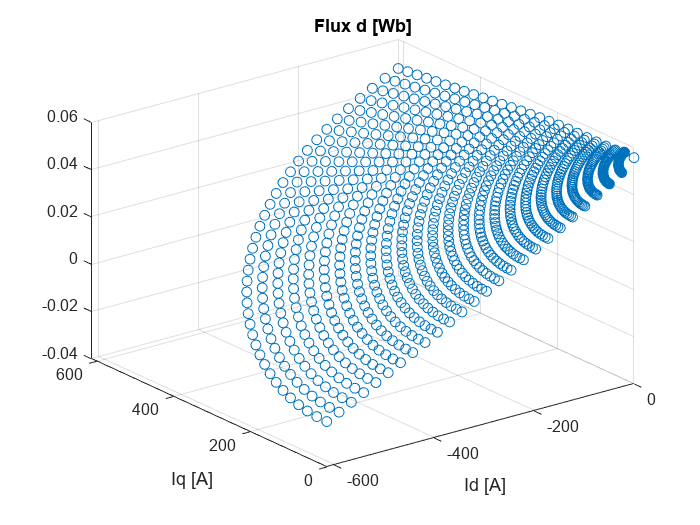

stem3(rawData.Id,rawData.Iq,rawData.Fluxd,"LineStyle","none");
title("Flux d [Wb]");
xlabel("Id [A]");ylabel("Iq [A]");

To visually check results, plot `Fluxq` with respect to `Id` and `Iq`.

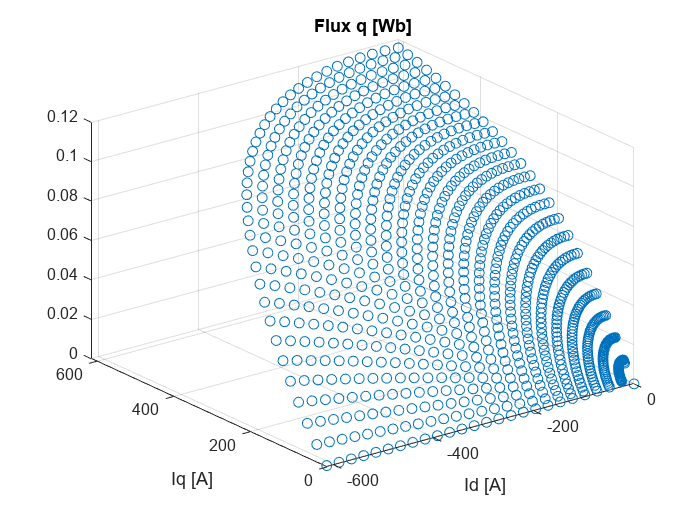

stem3(rawData.Id,rawData.Iq,rawData.Fluxq,"LineStyle","none");
title("Flux q [Wb]");
xlabel("Id [A]");
ylabel("Iq [A]");

To visually check results, plot `Id` and `Iq` with respect to `trq`.

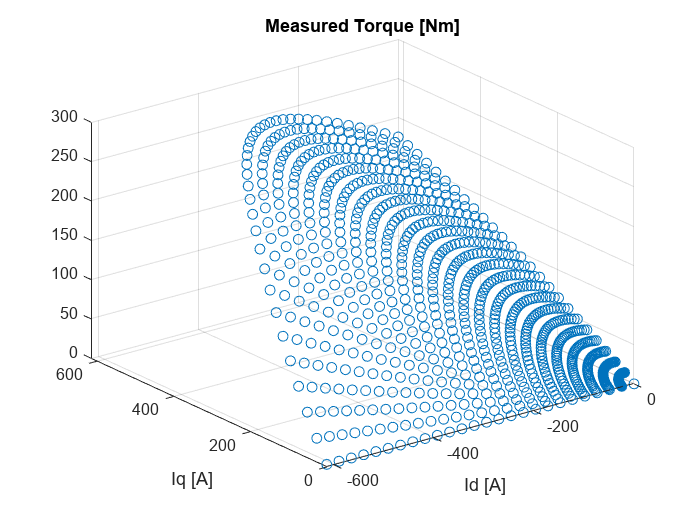

stem3(rawData.Id,rawData.Iq,rawData.Trq,"LineStyle","none");
title("Measured Torque [Nm]");
xlabel("Id [A]");
ylabel("Iq [A]");

## Convert Raw Data into Matrices and Visually Check Results

Calculate gridded data, [`IDgrid`,`IQgrid`], using [`ndgrid`](docid:matlab_ref#bvkap7w) to create a grid for `Fluxd` and `Fluxq`, bound by `IsMax`. Define the breakpoints in a cell array.

idAxis = linspace(-IsMax,0,51); 
iqAxis = linspace(0,IsMax,51);
[IDgrid,IQgrid] = ndgrid(idAxis,iqAxis);
currentBreakpoints = {idAxis,iqAxis};

## Fit `Flux d` Lookup Table

Using the current breakpoints and the raw data `rawData.Fluxd`, fit the lookup table `lambdad`. Plot the result using the `fitlookupn` function.

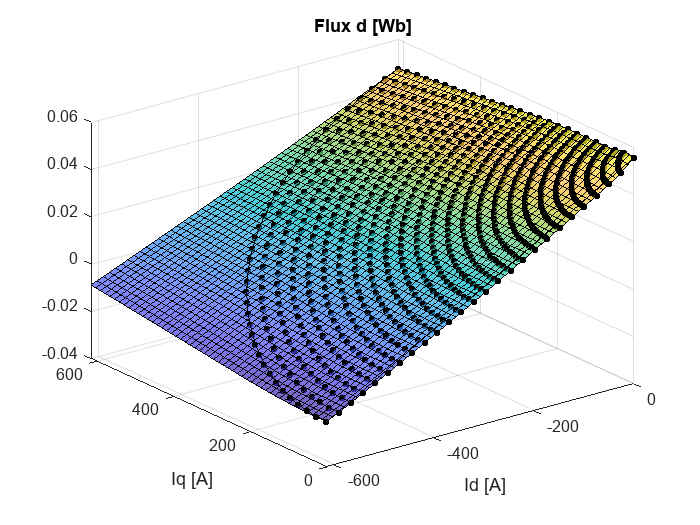

lambdad = fitlookupn(currentBreakpoints,[rawData.Id,rawData.Iq],rawData.Fluxd,ShowPlot=true);
title("Flux d [Wb]");
xlabel("Id [A]");
ylabel("Iq [A]");

## Fit `Flux q` Lookup Table

Using the current breakpoints and the raw data `Fluxq`, fit the lookup table `lambdaq`. Plot the result using the `fitlookupn` function.

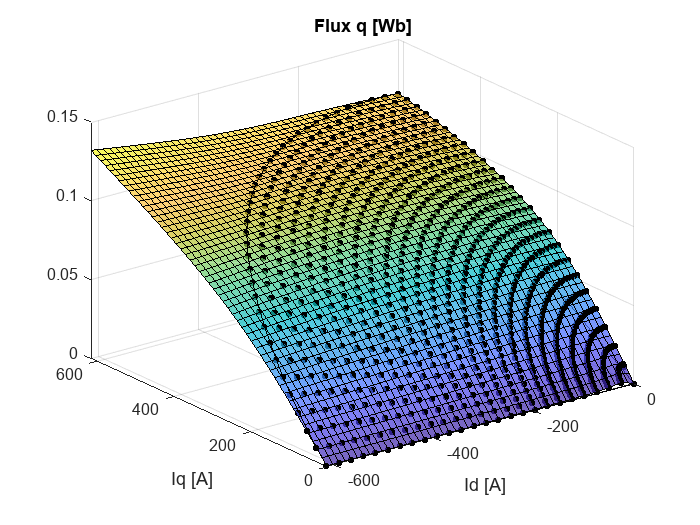

lambdaq = fitlookupn(currentBreakpoints,[rawData.Id,rawData.Iq],rawData.Fluxq,ShowPlot=true);
xlabel("Id [A]");
ylabel("Iq [A]");
title("Flux q [Wb]");

## Fit Torque Grid Lookup Table

Calculate generated torque from the raw flux and current data. Use the `fitlookupn` function to fit a lookup table with a spline approximation of 1 for additional smoothness for the calculated torque and the measured torque..

calculatedTorque = -1.5*pp*(rawData.Id.*rawData.Fluxq - rawData.Iq.*rawData.Fluxd);
calculatedTorqueGrid = fitlookupn(currentBreakpoints,[rawData.Id,rawData.Iq],calculatedTorque,1);
measuredTorque = fitlookupn(currentBreakpoints,[rawData.Id,rawData.Iq],rawData.Trq,1);

### Compare Measured and Calculated Torque

Compare the measured and calculated torque. Use a hot colormap (red) for the calculated torque surface.

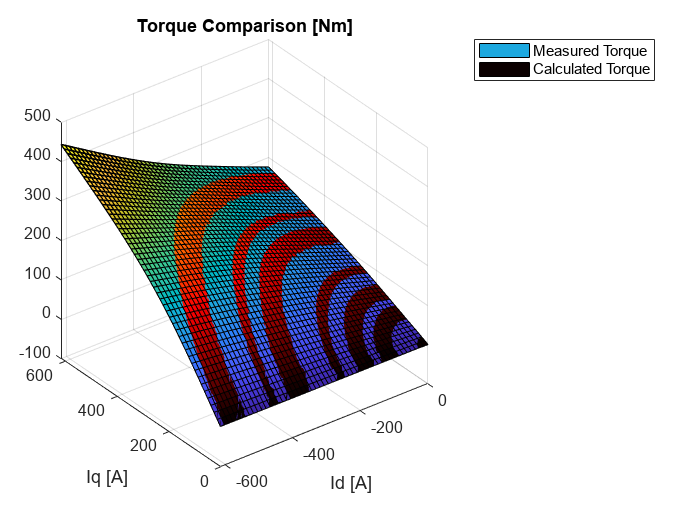

surf(IDgrid,IQgrid,measuredTorque,"DisplayName","Measured Torque");
cdata = mbcgui.graph.makeCData(calculatedTorqueGrid);
hold on
surf(IDgrid,IQgrid,calculatedTorqueGrid,"CData",cdata,"DisplayName","Calculated Torque");
title("Torque Comparison [Nm]");
xlabel("Id [A]");
ylabel("Iq [A]");
hold off
legend

### Plot Torque Error

Plot the difference in calculated torque and measured torque, resulting in the torque error.

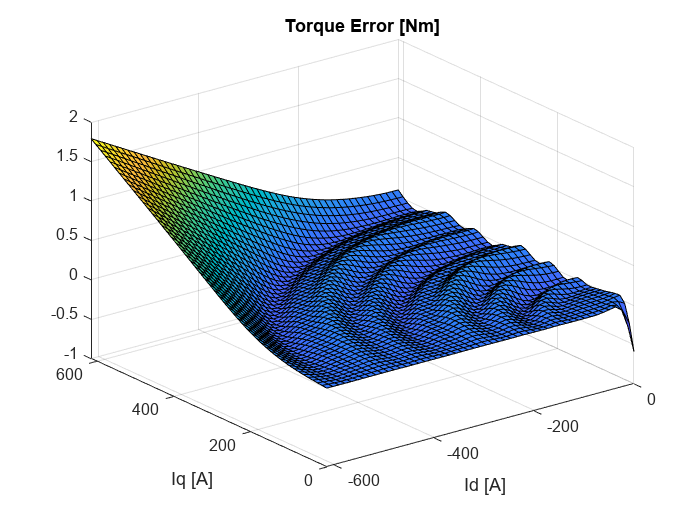

surf(IDgrid,IQgrid,measuredTorque- calculatedTorqueGrid);
title("Torque Error [Nm]");
xlabel("Id [A]");
ylabel("Iq [A]");

## Rearrange Data in Torque-Speed Operating Points

Introduce torque as an operating point in addition to speed by rearranging the data to have both torque and speed information.

### Calculate Torque Contour Levels

Initialize the torque contours at the levels in `minTorqueLevels`. Then, evenly space the levels up to the maximum measured torque.

TrqMax = max(abs(measuredTorque),[],"all");
numPoints = numTorqueLevels-length(minTorqueLevels)+1;
torqueLevels = [minTorqueLevels(1:end-1) linspace(minTorqueLevels(end),TrqMax,numPoints)];

### Create and Plot Torque Contour

Create and plot torque contour using the [`contour`](docid:matlab_ref#f19-795863) function.

`trqContour` is a 2x*N* array containing sets of contour data for each contour level.


$$\left\lbrack \begin{array}{cc}
Z_i  & X_i \\
N_i  & Y_i 
\end{array}\right\rbrack$$
 

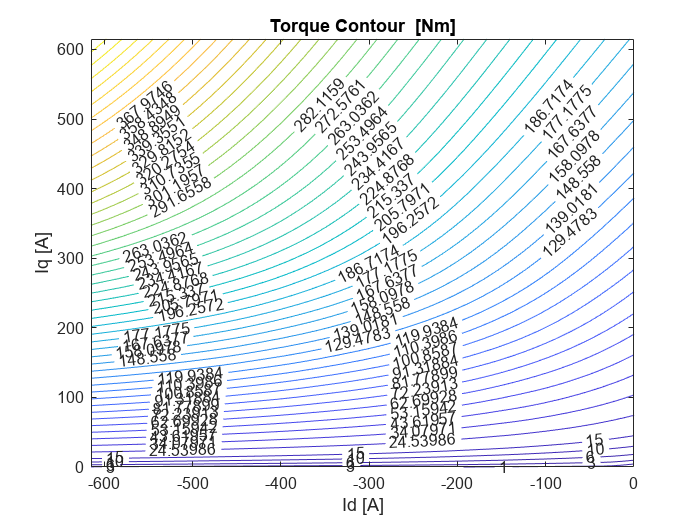

trqContour = contour(IDgrid,IQgrid,measuredTorque,torqueLevels,"ShowText","on");
title("Torque Contour  [Nm]");
xlabel("Id [A]");
ylabel("Iq [A]");

### Rearrange Data by Torque Levels

For each torque level, extract the `Trq`, `Id`, and `Iq` values. Next, downsample data for the torque level. If you have a Signal Processing Toolbox™ license, use the `downsample` function to calculate `dataDownsample`. Then, expand each torque level to include all speeds, attaching every speed operating point to each (`id`, `iq`) on the torque contour.

start = 1;
accumulatedData = []; 
while start < size(trqContour,2)
    % process each torque levels (the contour levels). There may be some
    % contour lines missing

    currentTorque = trqContour(1,start);

    % number of points in the contour for this torque
    ni = trqContour(2,start);
    stop = start + ni;
    
    % extract [Trq, Id, Iq] for current torque level 
    torqueData = [repelem(currentTorque,ni) ; 
    trqContour(:,start+1:stop)]'; % [Id, Iq] points for current torque
    
    if false % check to use downsample function.
        dataDownsample = downsample(torqueData,downsampleFactor);
    else
        dataDownsample = torqueData(1:downsampleFactor:end,:);
    end
    
    if ( dataDownsample(end,2)~= torqueData(end,2) ) 
        % make sure we have the last point in contour
        torqueData = [dataDownsample;torqueData(end,:)];
    else
        torqueData = dataDownsample;
    end
    ni = size(torqueData,1);
    
    % repeat torque contours for each speed and accumulate data
    % make sure speed is a column vector
    % [Trq, Id, Iq, n]
    accumulatedData=[accumulatedData;
        repmat(torqueData,[length(speed),1]) repelem(speed(:),ni)]; %#ok<AGROW> 

    % start of next torque contour
    start = stop+1;
end


## Create Table Object with Preprocessed Data

Store `accumulatedData` with the variables `Trq`, `Id`, `Iq`, and `n` to the table `MBCdata`.

MBCdata = array2table(accumulatedData,VariableNames=["Trq","Id","Iq","n"]);

Calculate the derived quantities peak current `MBCdata.Is`, voltage `MBCdata.Vs`, resultant flux `MBCdata.Flux`, and maximum flux `MBCdata.FluxMax`. Then, set the units of `MBCdata`.

MBCdata.Is = sqrt(MBCdata.Id.^2 + MBCdata.Iq.^2);

% electrical speed [rad/s]
we = 2*pi.*MBCdata.n.*pp./60;

Fluxd = interpn(idAxis,iqAxis,lambdad,MBCdata.Id,MBCdata.Iq);
Fluxq = interpn(idAxis,iqAxis,lambdaq,MBCdata.Id,MBCdata.Iq);

Vd = Rs.*MBCdata.Id - we.*Fluxq;
Vq = Rs.*MBCdata.Iq + we.*Fluxd;
MBCdata.Vs = sqrt(Vd.^2 + Vq.^2);

MBCdata.Flux = sqrt(Fluxd.^2 + Fluxq.^2);
MBCdata.FluxMax = sqrt(VsMax^2 - MBCdata.Is.^2*Rs^2 - 4*Rs.*we.*MBCdata.Trq/(3*pp))./we;
                                  % Trq  Id  Iq   n   Is   Vs  Flux FluxMax
MBCdata.Properties.VariableUnits = ["Nm","A","A","rpm","A","V","Wb","Wb"];

## Generate Excel Data File for MBC

Check the check box if you want to write data to an Excel file. 

Note that unit information will be lost.

if false % check to save data
    writetable(MBCdata,"PMSM_MBCData.xlsx");
end

## Generate Calibration

Automatically generate calibration using data for specified breakpoints using the `calibratepmsm` function. Run the function from the MATLAB command line with the option `Display=true` to show progress and final results in the MBC apps. Note that you cannot use the option `Display=true` within a Live Script. Do not run this code if you wish to manually calibrate the PMSM using the MBC apps.

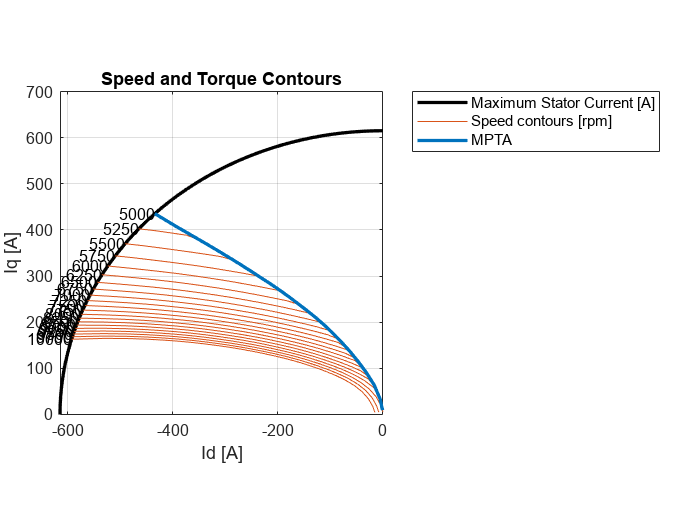

breakPoints = {speed, [1 4:4:100]};
[optimalTables,results] = calibratepmsm(MBCdata,IsMax,VsMax, ...
    TableType="speedtorquepercent",...
    Breakpoints=breakPoints, ...
    PlotResults=true);

## View Lookup Tables

### Torque Envelope

Plot the maximum torque envelope using `optimalTables.SpeedBreakpoints` and `optimalTables.TrqEnvelope`.

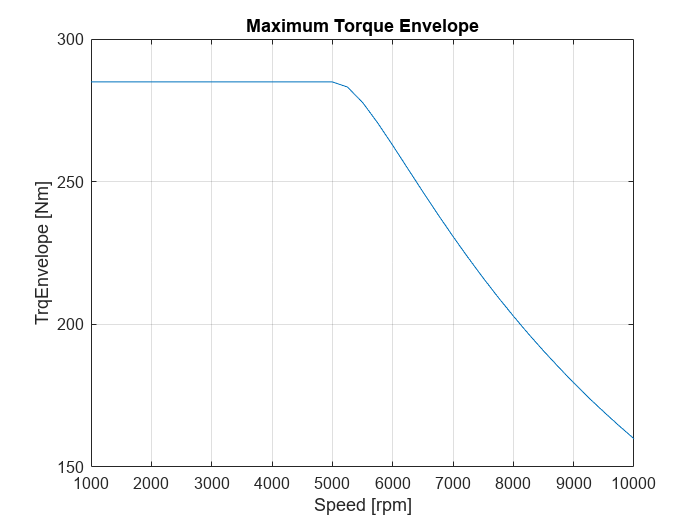

figure
plot(optimalTables.SpeedBreakpoints,optimalTables.TrqEnvelope);
xlabel("Speed [rpm]");
ylabel("TrqEnvelope [Nm]");
title("Maximum Torque Envelope");
grid on

### `Id` Table

Plot the `Id` Table using `optimalTables.TorquePercentBreakpoints`, `optimalTables.SpeedBreakpoints`, and `optimalTables.Id_Table`.

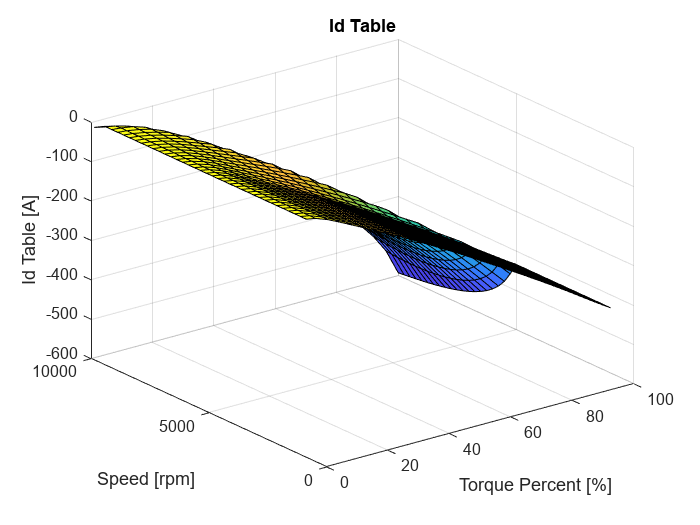

surf(optimalTables.TorquePercentBreakpoints,optimalTables.SpeedBreakpoints,optimalTables.Id_Table);
xlabel("Torque Percent [%]");
ylabel("Speed [rpm]");
zlabel("Id Table [A]");
title("Id Table");

### `Iq` Table

Plot the `Iq` Table using `optimalTables.TorquePercentBreakpoints`, `optimalTables.SpeedBreakpoints`, and `optimalTables.Iq_Table`.

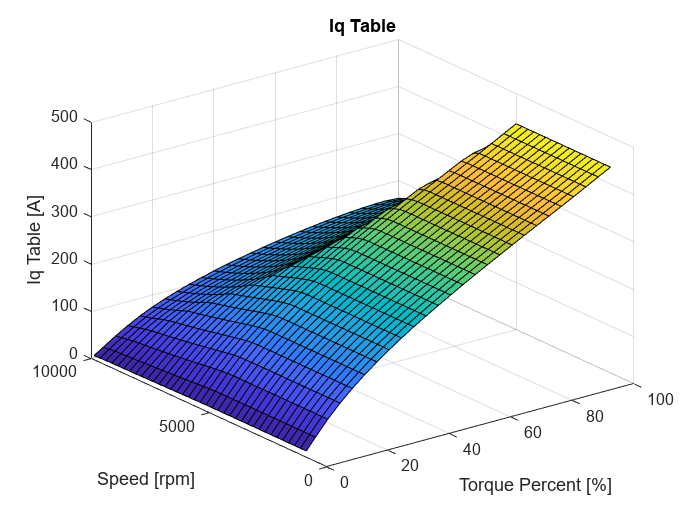

surf(optimalTables.TorquePercentBreakpoints,optimalTables.SpeedBreakpoints,optimalTables.Iq_Table);
xlabel("Torque Percent [%]");
ylabel("Speed [rpm]");
zlabel("Iq Table [A]");
title("Iq Table");

*Copyright 2023 The MathWorks, Inc.*